syms k1 k2 k3
%NPUT ANGLE
theta_2 = 40:5:60

theta_2 =     40    45    50    55    60


theta_4 = [70 76 83 91 100]

theta_4 =     70    76    83    91   100


fprintf(" theta 2 %.2f", theta_2)

 theta 2 40.00 theta 2 45.00 theta 2 50.00 theta 2 55.00 theta 2 60.00

fprintf(" theta 4 %.2f", theta_4)

 theta 4 70.00 theta 4 76.00 theta 4 83.00 theta 4 91.00 theta 4 100.00

matrix1 = zeros(3,3)

matrix1 =      0     0     0
     0     0     0
     0     0     0


matrix2 = zeros(3,1)

matrix2 =      0
     0
     0


for i = 1:5
 matrix1(1,1) = matrix1(1,1) + cosd(theta_4(i)).^2;
 matrix1(1,2) = matrix1(1,2) -cosd(theta_4(i)) * cosd(theta_2(i));
 matrix1(1,3) = matrix1(1,3) + cosd(theta_4(i));
 matrix1(2,1) = matrix1(2,1) + cosd(theta_2(i)) * cosd(theta_4(i));
 matrix1(2,2) = matrix1(2,2) -cosd(theta_2(i)).^2;
 matrix1(2,3) = matrix1(2,3) + cosd(theta_2(i));
 matrix1(3,1) = matrix1(3,1) + cosd(theta_4(i));
 matrix1(3,2) = matrix1(3,2) - cosd(theta_2(i));
 matrix1(3,3) = 5;
 matrix2(1,1) = matrix2(1,1) + cosd(theta_4(i)) * cosd(theta_2(i) -theta_4(i));
 matrix2(2,1) = matrix2(2,1) + cosd(theta_2(i)) * cosd(theta_2(i) -theta_4(i));
 matrix2(3,1) = matrix2(3,1) + cosd(theta_2(i) - theta_4(i));
 end

sol = linsolve(matrix1,matrix2)

sol =     1.0201
    1.6053
    1.7464



k1 = sol(1,1)

k1 = 1.0201

k2 = sol(2,1)

k2 = 1.6053

k3 = sol(3,1)

k3 = 1.7464


%finding lengths of links using ratios
d = 180

d = 180

a = abs(d/k1)

a = 176.4601

c = abs(d/k2)

c = 112.1312

b = (sqrt(a^2 -(2*a*c*k3) + c^2 + d^2))

b = 83.6747

fprintf(" a = %.2f ",a);

 a = 176.46 

fprintf(" b = %.2f ",b);

 b = 83.67 

fprintf(" c = %.2f ",c);

 c = 112.13 

fprintf(" k1 = %.2f k2 = %.2f k3 = %.2f",k1,k2, k3);

 k1 = 1.02 k2 = 1.61 k3 = 1.75

%part b
syms k1 k2 k3
theta_2 = 40:5:60

theta_2 =     40    45    50    55    60


theta_4 = [70 76 83 91 100]

theta_4 =     70    76    83    91   100


fprintf(" theta 2 %f", theta_2);

 theta 2 40.000000 theta 2 45.000000 theta 2 50.000000 theta 2 55.000000 theta 2 60.000000

fprintf(" theta 4 %f", theta_4);

 theta 4 70.000000 theta 4 76.000000 theta 4 83.000000 theta 4 91.000000 theta 4 100.000000

matrix1 = zeros(3,3)

matrix1 =      0     0     0
     0     0     0
     0     0     0


matrix2 = zeros(3,1)

matrix2 =      0
     0
     0


for i = 1:5
 matrix1(1,1) = matrix1(1,1) + cosd(theta_4(i)).^2;
 matrix1(1,2) = matrix1(1,2) -cosd(theta_4(i)) * cosd(theta_2(i));
 matrix1(1,3) = matrix1(1,3) + cosd(theta_4(i));
 matrix1(2,1) = matrix1(2,1) + cosd(theta_2(i)) * cosd(theta_4(i));
 matrix1(2,2) = matrix1(2,2) -cosd(theta_2(i)).^2;
 matrix1(2,3) = matrix1(2,3) + cosd(theta_2(i));
 matrix1(3,1) = matrix1(3,1) + cosd(theta_4(i));
 matrix1(3,2) = matrix1(3,2) - cosd(theta_2(i));
 matrix1(3,3) = 5;
 matrix2(1,1) = matrix2(1,1) + cosd(theta_4(i)) * cosd(theta_2(i) -theta_4(i));
 matrix2(2,1) = matrix2(2,1) + cosd(theta_2(i)) * cosd(theta_2(i) -theta_4(i));
 matrix2(3,1) = matrix2(3,1) + cosd(theta_2(i) - theta_4(i));
 end

sol = linsolve(matrix1,matrix2)

sol =     1.0201
    1.6053
    1.7464



k1 = sol(1,1)

k1 = 1.0201

k2 = sol(2,1)

k2 = 1.6053

k3 = sol(3,1)

k3 = 1.7464


%finding lengths of links using ratios
d=180;
a= abs(d/k1)

a = 176.4601

c= abs(d/k2)

c = 112.1312

b=(sqrt(a*a -(2*a*c*k3)+c*c + d*d));
fprintf("a=%f", a);

a=176.460128

fprintf("b=%f", b);

b=83.674719

fprintf("c=%f", c);

c=112.131155

%part b Transmission angle
inAngle = 40:1:60

inAngle =     40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60


transAngle = acosd(((b*b + c*c) - (a*a + d*d) + 2*a*d*cosd(inAngle))/(2*b*c))

transAngle =    75.4945   77.7545   80.0406   82.3550   84.7004   87.0795   89.4953   91.9513   94.4512   96.9996   99.6012  102.2619  104.9882  107.7879  110.6703  113.6464  116.7298  119.9374  123.2905  126.8170  130.5544


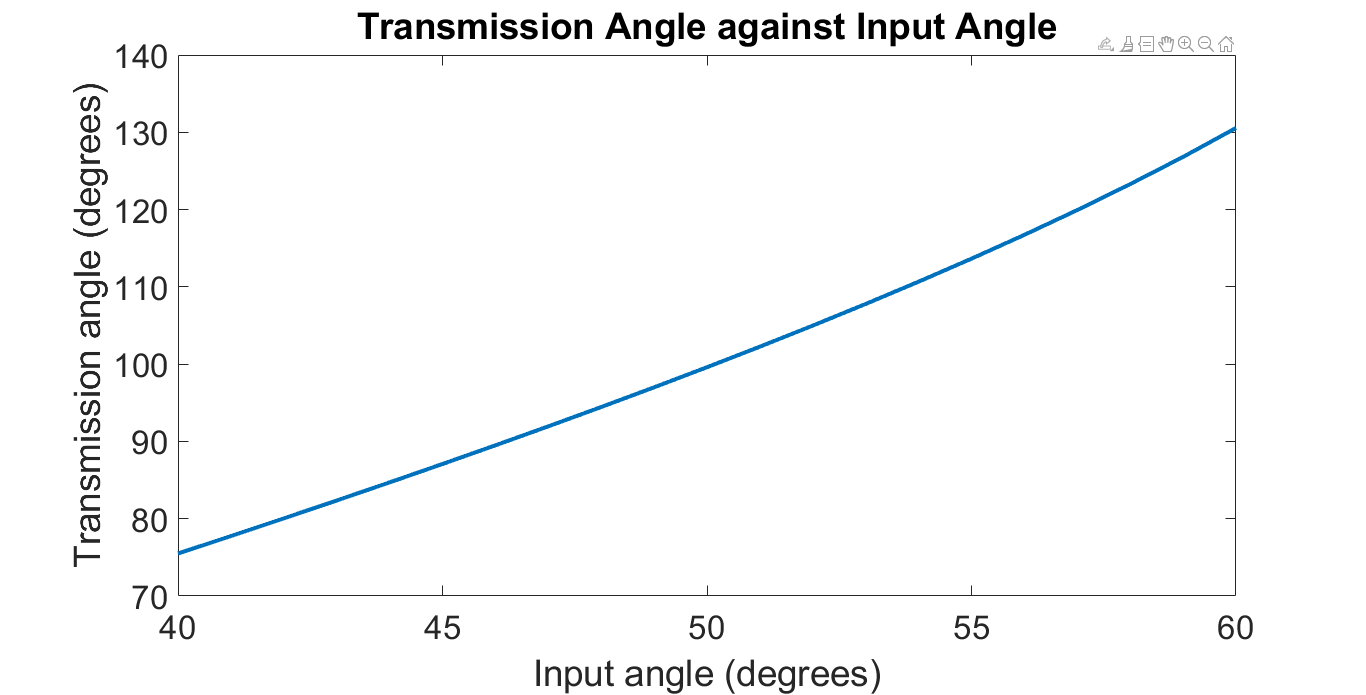

plot(inAngle,transAngle, 'Linewidth', 3)
title ('Transmission Angle against Input Angle')
ylabel('Transmission angle (degrees)')
xlabel('Input angle (degrees)')
set(gcf, 'Position', get(0, 'ScreenSize'));
set(gcf, 'Visible','on')
set(gca, 'FontSize', 25)

%part c
%relationship of theta_2 to theta_4
a = theta_2

a =     40    45    50    55    60


b = theta_4

b =     70    76    83    91   100


for i= 1:5
 ab(i) = a(i) * b(i)
end

ab = 2800

ab =         2800        3420


ab =         2800        3420        4150


ab =         2800        3420        4150        5005


ab =         2800        3420        4150        5005        6000


bSquared = b.^2

bSquared =         4900        5776        6889        8281       10000


aSquared = a.^2

aSquared =         1600        2025        2500        3025        3600


aR = (sum(b)*sum(aSquared) - sum(a)*sum(ab)) / (5 * sum(aSquared) - sum(a).^2)

aR = 9

bR = (5 * sum(ab) - sum(a) * sum(b)) / (5 * sum(aSquared) - sum(a).^2)

bR = 1.5000

theta2C = 40:1:60

theta2C =     40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60


theta4C = aR + bR * theta2C

theta4C =    69.0000   70.5000   72.0000   73.5000   75.0000   76.5000   78.0000   79.5000   81.0000   82.5000   84.0000   85.5000   87.0000   88.5000   90.0000   91.5000   93.0000   94.5000   96.0000   97.5000   99.0000


error = zeros(1,21)

error =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%get structural errors
for j = 1:length(theta2C)
 error(j) = k1 * cosd(theta4C(j)) - k2 * cosd(theta2C(j)) + k3 -cosd(theta2C(j) - theta4C(j))
end

error =     0.0076         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059         0         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068         0         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075         0         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079         0         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079         0         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077         0         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071         0         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062         0         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049         0         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033         0         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013         0         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013    0.0011         0         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013    0.0011    0.0039         0


error =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013    0.0011    0.0039    0.0070


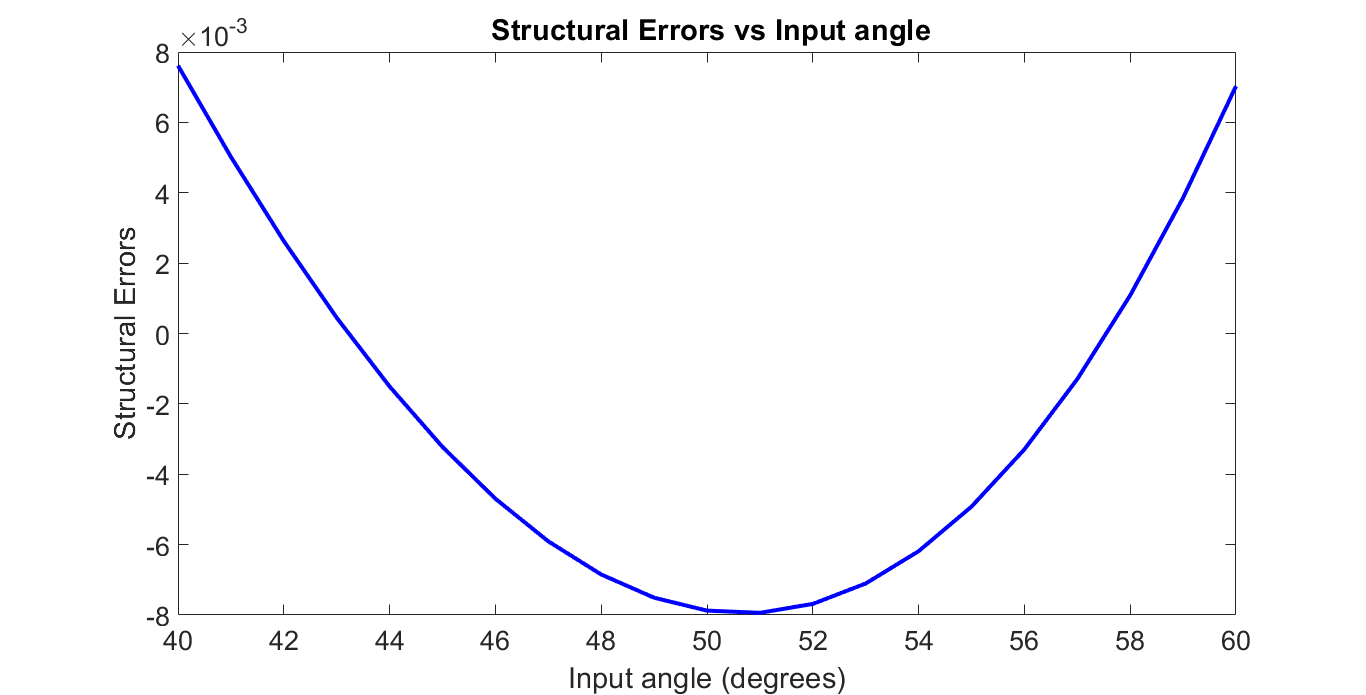

figure(2)
plot(theta2C, error, 'b', 'LineWidth',3 )
title(' Structural Errors vs Input angle')
xlabel('Input angle (degrees)')
ylabel('Structural Errors')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)